addpath('Data\')

g1_time = ParseMatlabAppFinal('G1');
g1_filt = move_avg_filt(g1_time, 3);
b1_time = ParseMatlabAppFinal('B1');
b1_filt = move_avg_filt(b1_time, 3);

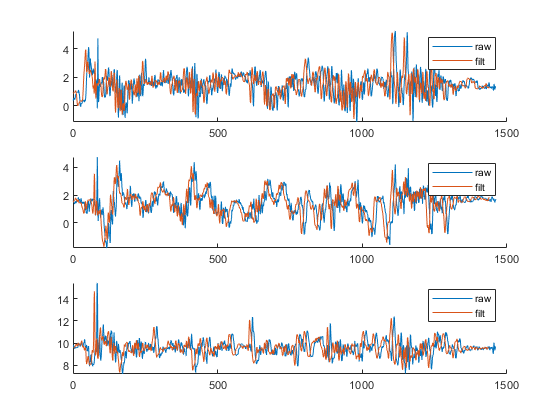

clf
figure()
subplot(3,1,1)
hold on
plot(g1_time.Accel(:,1))
plot(g1_filt(:,1))
hold off
legend('raw', 'filt')
subplot(3,1,2)
hold on
plot(g1_time.Accel(:,2))
plot(g1_filt(:,2))
hold off
legend('raw', 'filt')
subplot(3,1,3)
hold on
plot(g1_time.Accel(:,3))
plot(g1_filt(:,3))
hold off
legend('raw', 'filt')

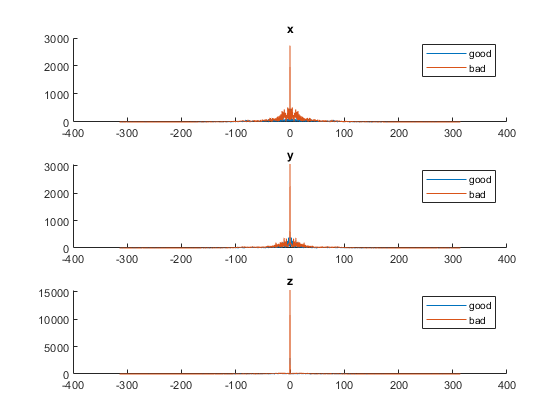

g1 = fft_from_time(g1_filt, 100);
b1 = fft_from_time(b1_filt, 100);
figure()
clf
subplot(3,1,1)
hold on
plot(g1(:,1), abs(g1(:,2)))
plot(b1(:,1), abs(b1(:,2)))
hold off
legend('good', 'bad')
title('x')
subplot(3,1,2)
hold on
plot(g1(:,1), abs(g1(:,3)))
plot(b1(:,1), abs(b1(:,3)))
hold off
legend('good', 'bad')
title('y')
subplot(3,1,3)
hold on
plot(g1(:,1), abs(g1(:,4)))
plot(b1(:,1), abs(b1(:,4)))
hold off
legend('good', 'bad')
title('z')

g1_time = ParseMatlabAppFinal('G1');
g1_filt = move_avg_filt(g1_time, 3);
g2_time = ParseMatlabAppFinal('G2');
g2_filt = move_avg_filt(g2_time, 3);
g3_time = ParseMatlabAppFinal('G3');
g3_filt = move_avg_filt(g3_time, 3);
g4_time = ParseMatlabAppFinal('G4');
g4_filt = move_avg_filt(g4_time, 3);


g1 = fft_from_time(g1_filt, 100);
g2 = fft_from_time(g2_filt, 100);
g3 = fft_from_time(g3_filt, 100);
g4 = fft_from_time(g4_filt, 100);

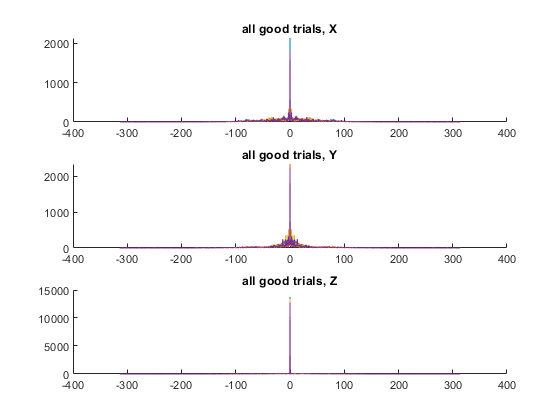

clf
figure();
subplot(3,1,1)
hold on
plot(g1(:,1), abs(g1(:,2)))
plot(g2(:,1), abs(g2(:,2)))
plot(g3(:,1), abs(g3(:,2)))
plot(g4(:,1), abs(g4(:,2)))
hold off
title('all good trials, X')
subplot(3,1,2)
hold on
plot(g1(:,1), abs(g1(:,3)))
plot(g2(:,1), abs(g2(:,3)))
plot(g3(:,1), abs(g3(:,3)))
plot(g4(:,1), abs(g4(:,3)))
hold off
title('all good trials, Y')
subplot(3,1,3)
hold on
plot(g1(:,1), abs(g1(:,4)))
plot(g2(:,1), abs(g2(:,4)))
plot(g3(:,1), abs(g3(:,4)))
plot(g4(:,1), abs(g4(:,4)))
hold off
title('all good trials, Z')

b1_time = ParseMatlabAppFinal('B1');
b1_filt = move_avg_filt(b1_time, 3);
b2_time = ParseMatlabAppFinal('B2');
b2_filt = move_avg_filt(b2_time, 3);
b3_time = ParseMatlabAppFinal('B3');
b3_filt = move_avg_filt(b3_time, 3);
b4_time = ParseMatlabAppFinal('B4');
b4_filt = move_avg_filt(b4_time, 3);


b1 = fft_from_time(b1_filt, 100);
b2 = fft_from_time(b2_filt, 100);
b3 = fft_from_time(b3_filt, 100);
b4 = fft_from_time(b4_filt, 100);

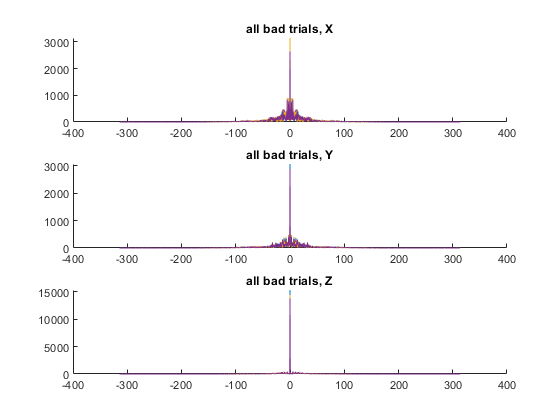

clf
figure();
subplot(3,1,1)
hold on
plot(b1(:,1), abs(b1(:,2)))
plot(b2(:,1), abs(b2(:,2)))
plot(b3(:,1), abs(b3(:,2)))
plot(b4(:,1), abs(b4(:,2)))
hold off
title('all bad trials, X')
subplot(3,1,2)
hold on
plot(b1(:,1), abs(b1(:,3)))
plot(b2(:,1), abs(b2(:,3)))
plot(b3(:,1), abs(b3(:,3)))
plot(b4(:,1), abs(b4(:,3)))
hold off
title('all bad trials, Y')
subplot(3,1,3)
hold on
plot(b1(:,1), abs(b1(:,4)))
plot(b2(:,1), abs(b2(:,4)))
plot(b3(:,1), abs(b3(:,4)))
plot(b4(:,1), abs(b4(:,4)))
hold off
title('all bad trials, Z')

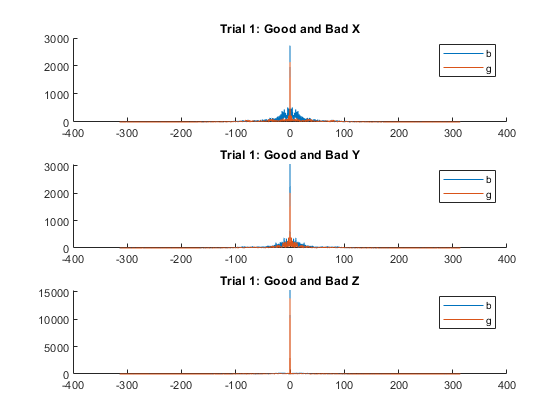

figure();
subplot(3,1,1)
hold on
plot(b1(:,1), abs(b1(:,2)))
plot(g1(:,1), abs(g1(:,2)))
legend("b", "g")
title("Trial 1: Good and Bad X")
hold off
subplot(3,1,2)
hold on
plot(b1(:,1), abs(b1(:,3)))
plot(g1(:,1), abs(g1(:,3)))
legend("b", "g")
title("Trial 1: Good and Bad Y")
hold off
subplot(3,1,3)
hold on
plot(b1(:,1), abs(b1(:,4)))
plot(g1(:,1), abs(g1(:,4)))
legend("b", "g")
title("Trial 1: Good and Bad Z")
hold off